# Simulation Dynamics

This section presents the simulation dynamics of the model.

We begin by computing the baseline transition path of the economy under Business-As-Usual assumptions.

We then introduce an alternative carbon-policy scenario and solve for the corresponding transition to a net-zero economy.

Finally, we compare the two deterministic trajectories to assess the macroeconomic and climate implications of stronger mitigation efforts.

## I. Initialization of the path of the model

We start by loading the model using Dynare:

dynare model_file

Starting Dynare (version 6.4).
Calling Dynare with arguments: none
Starting preprocessing of the model file ... 
Substitution of exo lags: added 1 auxiliary variables and equations. 
Found 62 equation(s). 
Evaluating expressions... 
Computing static model derivatives (order 1). 
Normalizing the static model... 
Normalization failed with cutoff, trying symbolic normalization... 
Finding the optimal block decomposition of the static model... 
30 block(s) found: 
  29 recursive block(s) and 1 simultaneous block(s). 
  the largest simultaneous block has 10 equation(s) 
                    


STEADY-STATE RESULTS:

Z                		 22.9448
L                		 10.48
gZ               		 0
gL               		 0
SIG              		 0
gSIG             		 0
THETA1           		 0
delthet          		 0
dy               		 0
de               		 0
pi               		 0.0025
r                		 0.00223451
y                		 0.978583
x                		 0.9875
M                		 1889.6
mc               		 0.75
y_n              		 0.978583
x_n              		 0.9875
rr_n             		 -0.000264827
pi_bar           		 0.0025
D                		 0.893446
s_r              		 1
s_p              		 1
s_b              		 1
s_e              		 1
mu               		 0.0001
c                		 0.966351
lb               		 1.06575
rotemberg_to_gdp 		 1.25
abatement_to_gdp 		 0
tau_USD          		 0
h                		 1.03833
d                		 0.953151
tau              		 3.98107e-07
E                		 0
rr_real          		 -0.000264827
pi100            		 0.25
rr100            		 0.223


% solve the path for business as usual
[y_guess,oo_,M_]		= EP_paths_init(oo_,M_,options_,exo_init_ts);
[y_bau] 				= EP_deterministic_path(y_guess,exo_init_ts,oo_,M_,options_);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 78.5548,	 time = 0.383
Iter: 2,	 err. = 79.7931,	 time = 0.139
Iter: 3,	 err. = 0.0195392,	 time = 0.237
Iter: 4,	 err. = 7.29728e-06,	 time = 0.12

Total time of simulation: 1.366.
--------------------------------------------------------



## II. Scenario: transition with alternative carbon policy

### A. Solving the transition to net zero economy

We now consider a transition scenario in which the implementation of the carbon tax is modified. This is captured by updating the terminal state of the model with a new value of the policy parameter `varphi`. The routine `update_terminal_state` adjusts the long run conditions of the economy (for example, the terminal carbon stock and productivity) consistently with this new policy.

In the business-as-usual scenario, it is assumed that carbon tax path does not materializes: phi*tau with phi=0. But the tax path consistent with Paris-Agreement actually exists:

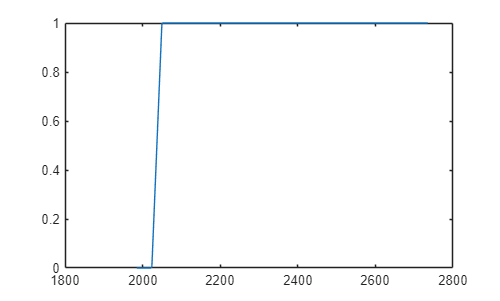

figure;
plotds('e_tau',exo_init_ts)

where 1 means net zero transition. This is the path of the detrended carbon tax.

Using the updated structures `(oo_nz0, M_nz0)` and the corresponding initial guess `y_nz0`, we then recompute the deterministic transition path with `EP_deterministic_path`. The resulting path describes how the economy evolves under this alternative carbon policy scenario.

% Update terminal state for a scenario with varphi = 1
[y_nz0, oo_nz0, M_nz0] = update_terminal_state('varphi', 1, ...
                                               oo_, M_, exo_init_ts, y_guess);

% Step 1: Compute the deterministic path under the new policy
[y_nz0] = EP_deterministic_path(y_nz0, exo_init_ts, oo_nz0, M_nz0, options_);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 8.10664,	 time = 0.066
Iter: 2,	 err. = 0.346549,	 time = 0.063
Iter: 3,	 err. = 0.000242085,	 time = 0.065
Iter: 4,	 err. = 1.90761e-08,	 time = 0.063

Total time of simulation: 0.337.
--------------------------------------------------------



### B. Plotting the final figure

We now compare the deterministic transition of the economy under two policy scenarios:

- a Business-As-Usual (BAU) path `y_bau`,

- a Paris-Agreement-style path `y_nz0`, where the carbon policy is tightened.

The figure below plots key macroeconomic and climate variables under both scenarios over the period 2000–2100. This highlights how output, consumption, labor, damages, the carbon tax in USD, emissions, temperature, and the carbon stock respond to stronger climate policy relative to BAU.

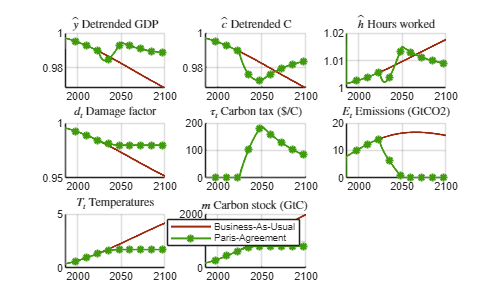

nx = 3;ny = 3;varnames=char('y','c','h','d','tau_USD','E','T','M');
nn=size(varnames,1);
figure('Name','Figure 3: Comparison of transitions (deterministic)');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	hold on;
	plotds(varnames(i1,:),y_bau,'Color',[156, 40, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_bau,1))
	plotds(varnames(i1,:),y_nz0,'*-','Color',[64, 156, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_nz0,1))
	hold off;
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([1985.25 2100])
end
legend('Business-As-Usual','Paris-Agreement')

## III. Delaying the implementation of the carbon tax to 2100

We now modify the exogenous path of the carbon tax shock `e_tau` to impose a more gradual and delayed implementation.

Instead of ramping up from the start of the simulation, the tax now increases linearly from zero to its full level between 2023Q4 and 2100Q4, and then remains constant.

We construct a new exogenous dataset `exo_init_ts2` with this delayed tax path and use it to recompute the deterministic transition under the same net-zero policy parameters. The resulting path, `y_nz02`, describes a transition where the effective carbon tax is postponed relative to the baseline net-zero scenario.

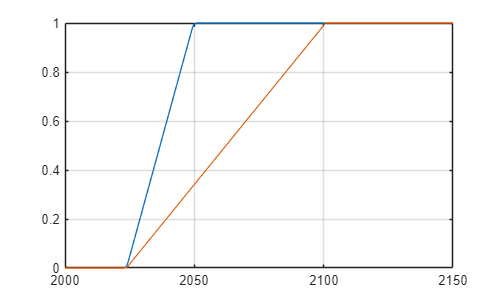

% making a copy
idtau     						 = strmatch('e_tau',M_.exo_names,'exact');
id_now    						 = find(exo_init_ts.dates==dates('2023Q3')+1);		% initial period of simulation
id_taxmax 						 = find(exo_init_ts.dates==dates('2100Q4'));		% when policy is fully implemented
exo_init2 						 = exo_init_ts.data;
exo_init2(id_now:id_taxmax,idtau) = linspace(0,1,(id_taxmax-id_now)+1);
exo_init2(id_taxmax:end,idtau)    = 1;
exo_init_ts2 					 = dseries(exo_init2,exo_init_ts.dates(1),exo_init_ts.name);

figure;
plotds('e_tau',exo_init_ts)
hold on;
plotds('e_tau',exo_init_ts2)
hold off;
xlim([2000 2150])
grid on;


% Step 1: Compute the deterministic path under the new policy
[y_nz02] = EP_deterministic_path(y_nz0, exo_init_ts2, oo_nz0, M_nz0, options_);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.655516,	 time = 0.094
Iter: 2,	 err. = 0.183253,	 time = 0.087
Iter: 3,	 err. = 2.87865e-05,	 time = 0.093
Iter: 4,	 err. = 4.2103e-12,	 time = 0.078

Total time of simulation: 0.513.
--------------------------------------------------------



We now compare the deterministic transition under two versions of the net-zero policy:

- **Paris-Agreement scenario** `y_nz0`, where the carbon tax ramps up immediately according to the baseline transition path.

- **Delayed-transition scenario** `y_nz02`, where the carbon tax is postponed and only reaches its full level by 2100.

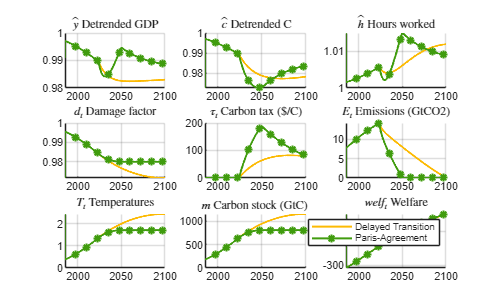

nx = 3;ny = 3;varnames=char('y','c','h','d','tau_USD','E','T','M','welfare');
nn=size(varnames,1);
figure('Name','Figure 3: Comparison of transitions (deterministic)');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	hold on;
	plotds(varnames(i1,:),y_nz02,'Color',[252, 186, 3]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_bau,1))
	plotds(varnames(i1,:),y_nz0,'*-','Color',[64, 156, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_nz0,1))
	hold off;
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([1985.25 2100])
end
legend('Delayed Transition','Paris-Agreement')

## IV. Optimal carbon tax

We now compute the social cost of carbon (SCC) by optimizing the path of the carbon tax shock `e_tau` over a given horizon. The idea is to treat the tax path as a control variable and choose it to maximize welfare (or equivalently minimize the negative of welfare) along the transition.

We select welfare as the objective variable and the path of `e_tau` between 2025Q1 and 2100Q1 as the control. Using `fmincon`, we solve for the welfare-maximizing tax trajectory subject to bounds between 0 and 1, starting from the nominal BAU path. The resulting optimized tax sequence defines the implied SCC along the transition.

update_path_dates 	= dates('2025Q1'):dates('2100Q4');
scc_ts              = solve_optimal_policy('e_tau','welfare',update_path_dates,exo_init_ts,y_nz0,oo_nz0,M_nz0,options_);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0          39    2.398716e+02     0.000e+00     1.000e+00     0.000e+00     1.022e-01  
    1          78    2.397707e+02     0.000e+00     1.000e+00     3.422e-01     8.352e-02  
    2         117    2.396293e+02     0.000e+00     1.000e+00     1.340e+00     2.176e-01  
    3         156    2.395857e+02     0.000e+00     1.000e+00     3.429e-01     3.402e-02  
    4         195    2.395688e+02     0.000e+00     1.000e+00     2.472e-01     2.475e-02  
    5         234    2.395548e+02     0.000e+00     1.000e+00     3.701e-01     2.674e-02  
    6         273    2.395504e+02     0.000e+00     1.000e+00     1.201e-01     1.925e-02  
    7         312    2.395461e+02     0.000e+00     1.000e+00     1.739e-01     1.107e-02  
    8         351    2.395448e+02     0.000e+00     1.000e+00     7.544e-02     9.

[det_nz0_1] 		= EP_deterministic_path(y_nz0,scc_ts,oo_nz0,M_nz0,options_);


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.645703,	 time = 0.481
Iter: 2,	 err. = 0.172555,	 time = 0.487
Iter: 3,	 err. = 2.67783e-05,	 time = 0.462
Iter: 4,	 err. = 3.15858e-12,	 time = 0.529

Total time of simulation: 2.286.
--------------------------------------------------------



Then solve and plot

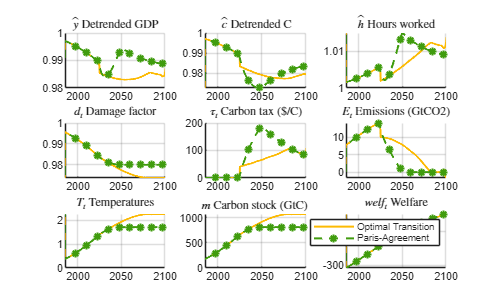

nx = 3;ny = 3;varnames=char('y','c','h','d','tau_USD','E','T','M','welfare');
nn=size(varnames,1);
figure('Name','Figure 3: Comparison of transitions (deterministic)');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	hold on;
	plotds(varnames(i1,:),det_nz0_1,'Color',[252, 186, 3]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(det_nz0_1,1))
	plotds(varnames(i1,:),y_nz0,'*--','Color',[64, 156, 14]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(y_nz0,1))
	hold off;
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([1985.25 2100])
end
legend('Optimal Transition','Paris-Agreement')